# Simulationsaufgabe Variante 3

## 🟰 Bewegungsgleichungen gekoppelter Oszillatoren

### Erzwungen


$$ $\ddot{\varphi}_1 + \frac{b}{J}\dot{\varphi}_1 + \frac{D_1}{J}\varphi_1 + \frac{D_2}{J}(\varphi_1 - \varphi_2) = \hat{M}_e\sin(\omega_e t)$$$



$$  $\ddot{\varphi}_2 + \frac{b}{J}\dot{\varphi}_2 + \frac{D_1}{J}\varphi_2 + \frac{D_2}{J}(\varphi_2 - \varphi_1) = 0$$$


### Frei


$$$\ddot{\varphi}_1 + \frac{b}{J}\dot{\varphi}_1 + \frac{D_1}{J}\varphi_1 + \frac{D_2}{J}(\varphi_1 - \varphi_2) = 0$$$



$$$\ddot{\varphi}_2 + \frac{b}{J}\dot{\varphi}_2 + \frac{D_1}{J}\varphi_2 + \frac{D_2}{J}(\varphi_2 - \varphi_1) = 0$$$


## 🎛️ Systemparameter

clf;
clear all;
% addpath('Simulationsaufgabe\');
J = 10;
D1 = 0.1;
D2 = 0.01;
b = 0.2;
alpha_emax = 50;
m = 0;
dm = 100;
f_e = 1;

### Anfangsbedingunge️n


phi1_0 = 0;
phi2_0 = 0;
omega1_0 = 0;
omega2_0 = 0;

% --- Umrechnungen ---

ic_deg = [phi1_0 phi2_0 omega1_0 omega2_0];
ic_rad = deg2rad(ic_deg);

delta = b/(2*J);
omega_a = sqrt(D1/J); % Eigenwinkelfreq a
omega_b = sqrt((D1+D2)/J); % Eigenwinnkelfreq b
f_a = omega_a/(2*pi); % Eigenfreq a
T_a = 1/f_a; % Periodendauer a

% --- Erregerstuff ---

M_emax = alpha_emax*D1; % Erregermoment (max)
if f_e == 0
    T_e = inf;
else
    T_e = 1/f_e; % Erreger Periodendauer
end
omega_e = f_e*2*pi; % Erreggerfreq. zu Winkelfreq

Die *langsame* Frequenz ergibt sich durch $\omega_a = \sqrt{\frac{D_1}{J}}$, die *schnelle* Frequenz durch $\omega_b = \sqrt{\frac{D_1+D_2}{J}}$ bzw. $\sqrt{\frac{2D_1}{J}} = \sqrt{\frac{2D_2}{J}}$ für den Fall gleicher Federkonstanten. Die Auswahl der Anzahl der zu berechnenden Periodenn bezieht sich auf die *schnellere* Frequenz. Abgetastet wird mit 100 Werten je schneller Periodendauer.

### Presets

p = false; e = true; g = true; U = false;

% Bits: | e | g | U | e=erzwungen, g=gedämpft, U=Unwucht
%       |---|---|---|
%       | 0 | 0 | 0 | 'Frei, ungedämpft ohne Unwucht'
%       | 0 | 0 | 1 | 'Frei, gedämpft ohne Unwucht'
%       | 0 | 1 | 0 | 'Frei, ungedämpft mit Unwucht'
%       | 0 | 1 | 1 | 'Frei, gedämpft mit Unwucht'
%       | 1 | 0 | 0 | 'Erzwungen, ungedämpft ohne Unwucht'
%       | 1 | 0 | 1 | 'Erzwungen, gedämpft ohne Unwucht'
%       | 1 | 1 | 0 | 'Erzwungen, ungedämpft mit Unwucht'
%       | 1 | 1 | 1 | 'Erzwungen, gedämpft mit Unwucht'
if p == true
    if e == true
        alpha_emax = 90;
        f_e = 2;
        etext = 'Erzwungen';
    elseif e == false
        etext = 'Frei';
    end
    if g == true
        b = 10;
        gtext = 'Gedämpft';
    elseif g == false
        gtext = 'Ungedämpft';
    end
    if U == true
        m = 1000;
        Utext = 'mit Unwucht';
    elseif U == false
        Utext = 'ohne Unwucht';
    end
    text = strcat(etext,', ',gtext,', ',Utext);
elseif p == false
    text = '';
end

## 📜 Plot Config

### Größe und Seitenverhältnis

screensize = get(0,'ScreenSize');
fwidth = .75*screensize(3);
fheight = .75*screensize(4);
override = true;
if override == true
    ws = [2544 1920 1680 1600 1440 1366 1280 1024 768 512];
    aspect_ratio = 16/9;
    fwidth = 1024;
    fheight = fwidth/aspect_ratio;
end


dgl = @(t,u)dgl_1_24a(t, u, J, b, D1, D2, M_emax, omega_e, m);

f = [f_e f_a];
n = 100/max(f); % 100 points per shorter period
periods = 100;
tspan = linspace(0,periods*1/max(f),ceil(periods*n));

[t,u] = ode45(dgl, tspan, ic_rad);

alpha_e = alpha_emax*sin(omega_e.*t);
phi1 = u(:,1);
phi2 = u(:,2);
omega1 = u(:,3);
omega2 = u(:,4);

## ✍️ Plotten

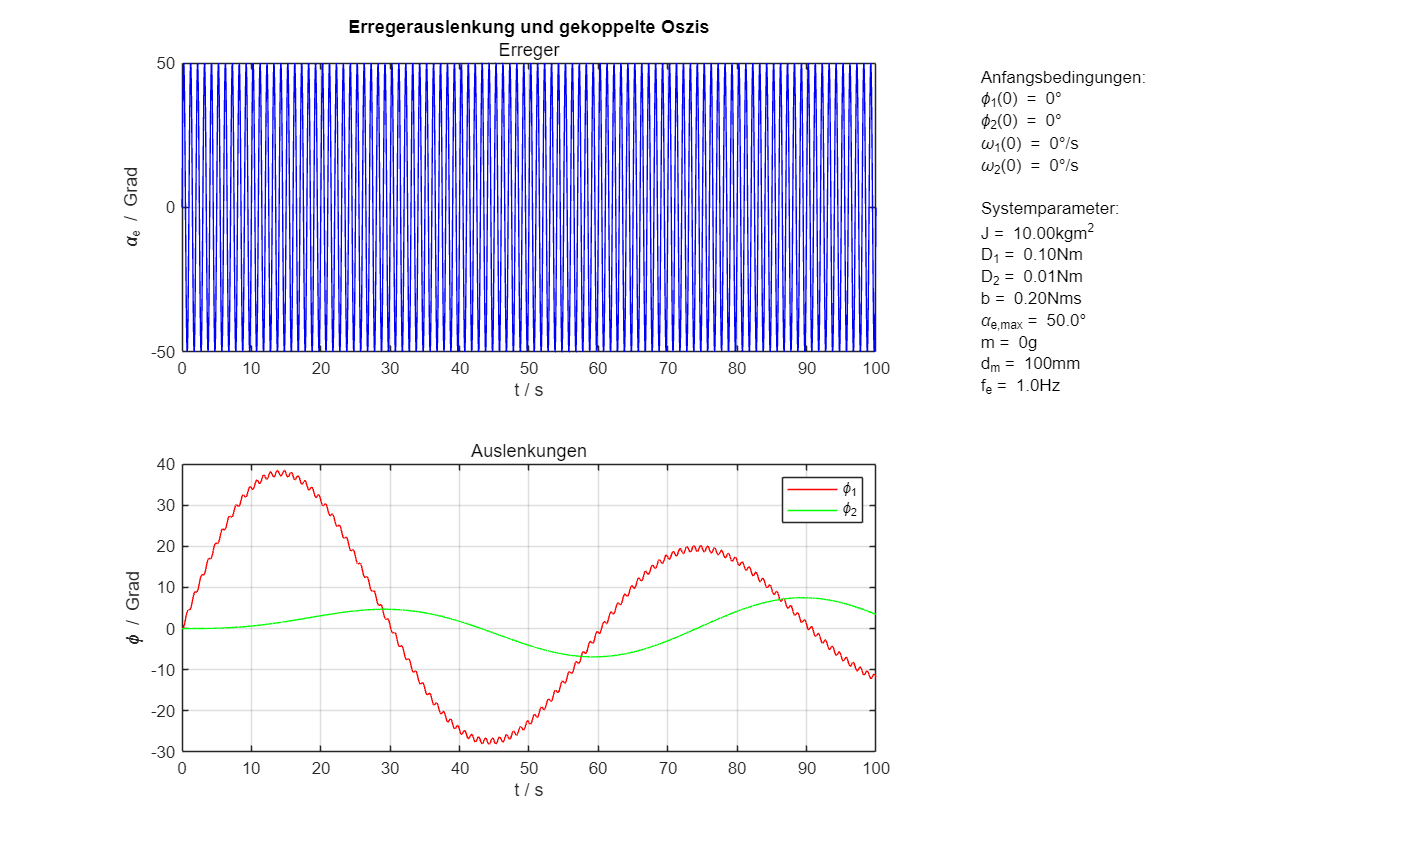

 
% Subplot erstellen
clf;
subplot(2,3,[1,2]);
pos = get(gcf, 'Position');
set(gcf, 'Position', pos+[0 0 fwidth fheight]); % left bottom width height

% Erregerfrequenz und -auslenkung plotten und Plot formatieren
plot(t,alpha_e, 'b');
ylabel('\alpha_e / Grad')
xlabel('t / s')
% title(sprintf('Erregerauslenkung und gekoppelte Oszis bei Anfangsbedingungen:\n\\phi_1(0) = %d°, \\phi_2(0) = %d°, \\omega_1(0) = %d°/s, \\omega_2(0) = %d°/s', ic_deg));
title('Erregerauslenkung und gekoppelte Oszis')
subtitle('Erreger');
grid on

% Auslenkungen der beiden Räder plotten und Plot formatieren
subplot(2,3,[4,5])
plot(t, rad2deg(phi1), 'r');
hold on
plot(t, rad2deg(phi2), 'g');
ylabel('\phi / Grad')
xlabel('t / s')
subtitle('Auslenkungen');
% zeroline = refline(0, 0); % Referenzlinie bei y=0 ...
% zeroline.Color = 'k'; % in schwarz
grid on
legend('\phi_1','\phi_2');

subplot(2,3,[3,6])
format short
ab_text = sprintf([ ...
    'Anfangsbedingungen:\n' ...
    '\\phi_1(0) = %d°\n' ...
    '\\phi_2(0) = %d°\n' ...
    '\\omega_1(0) = %d°/s\n' ...
    '\\omega_2(0) = %d°/s' ...
    ], ic_deg);
params_text = sprintf([ ...
    '\n\nSystemparameter:\n' ...
    'J\t= %.2fkgm^2\n' ...
    'D_1\t= %.2fNm\n' ...
    'D_2\t= %.2fNm\n' ...
    'b\t= %.2fNms\n' ...
    '\\alpha_{e,max}\t= %.1f°\n' ...
    'm\t= %dg\n' ...
    'd_m\t= %dmm\n' ...
    'f_e\t= %.1fHz' ...
    ], J, D1, D2, b, alpha_emax, m, dm, f_e);
anpos = get(gca, 'Position');
annotation('textbox', [anpos(1), anpos(2), anpos(3), anpos(4)], 'String', strcat(ab_text, params_text), 'LineStyle', 'none');
% annotation('textbox', [0.66, 0.8, 0.1, 1], 'String', strcat(ab_text, params_text));
axis off

## 🎞️ Animation generieren

***Vorsicht:**** kann je nach gewählten Parametern eine Weile dauern!*

*Der Slider verwirft bei der Animation jedes nte Element. Zu hohe Werte können zu verzerrten Darstellungen führen (Nyquist).*

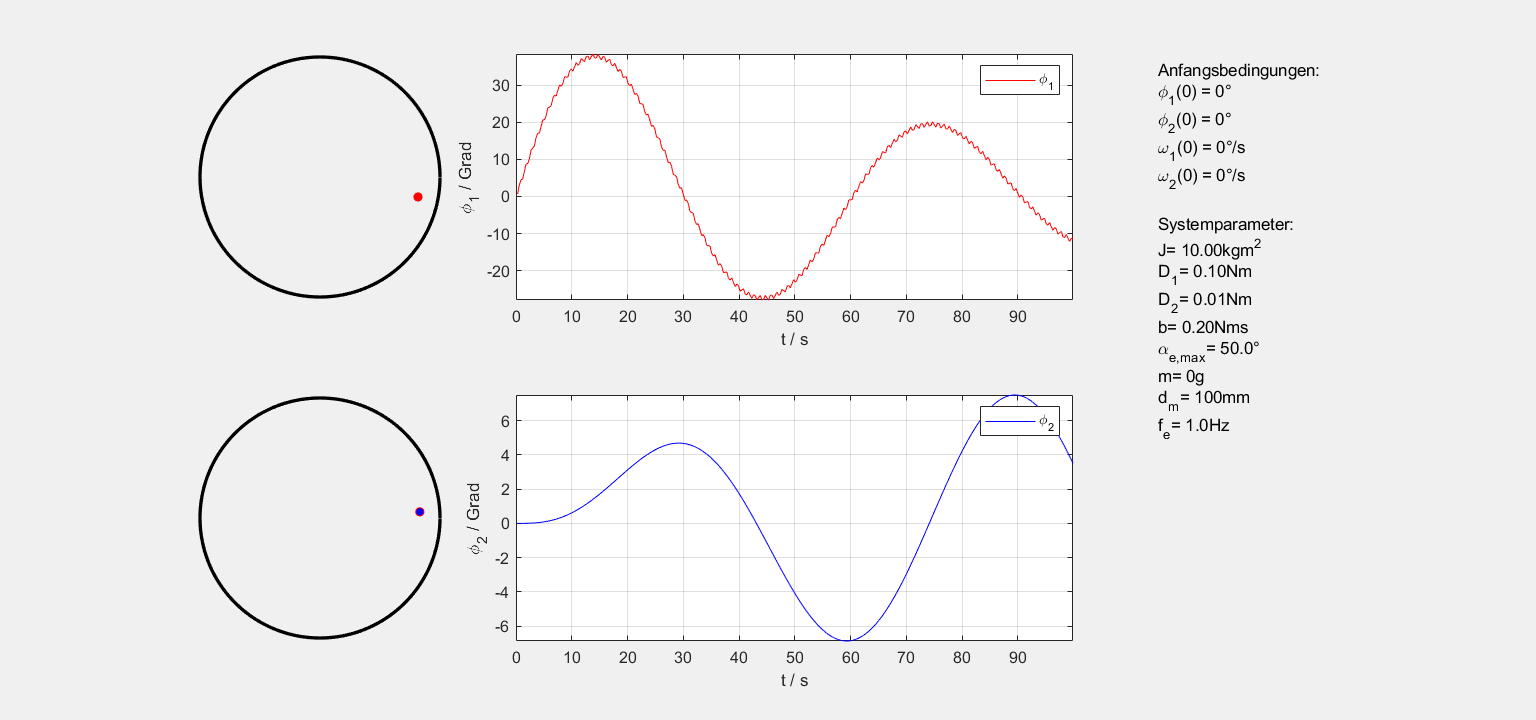

tres = 30;  
clear M;
tic
M = makeAnim(J, D1, D2, b, alpha_emax, m, dm, f_e, t, phi1, phi2, ic_deg, tres);

toc

Elapsed time is 63.070039 seconds.


### Animation als video speichern

clear vfile;
vfile = "anim";  
[fPath, fName, fExt] = fileparts(vfile);
if ~isequal(lower(fName), "")
    v = VideoWriter("anim",'MPEG-4');
    v.FrameRate = 10;
    open(v)
    for k = 1:length(M)
        writeVideo(v,M(k))
    end
    close(v)

    fprintf("Video erfolgreich gespeichert als %s%s", [fName, ".mp4"])
else
    fprintf("Bitte einen Dateinamen wählen...")
end

Video erfolgreich gespeichert als anim.mp4

## 💾 Daten speichern und laden

clear sfile;
sfile = "defaults";  
[fPath, fName, fExt] = fileparts(sfile);
if ~isequal(lower(fName), "")
    save(sfile, "t", "alpha_e", "phi1", "phi2", "omega1", "omega2", "ic_deg", "J", "D1", "D2", "b", "alpha_emax", "m", "dm", "f_e");
    fprintf("Daten erfolgreich gespeichert als \'%s%s\'", [fName, fExt])
    sfile = "";
else
    fprintf("Bitte einen Dateinamen wählen...")
    sfile = "";
end
clear lfile;
lfile = "";  
[fPath, fName, fExt] = fileparts(lfile);
if ~isequal(lower(fExt), ".mat")
    file = "";
    disp("Meh, bitte eine .mat auswählen.")
    clear lfile;
end
if exist("t", "var") && exist("alpha_e", "var") && exist("phi1", "var") && exist("phi2", "var") && exist("omega1", "var") && exist("omega2", "var")
    fprintf("%s%s erfolgreich geladen.\n", [fName fExt])
    lfile = "";
end

## 🤔 Infos

 
help

## 💁 Funktionen

function du=dgl_1_24a(t,u,J,b,D1,D2,Memax,we,m)
    % Vektor du = [phi1, phi2, omega1, omega2]
    % omega1=dphi1, omega2=dphi2
     
    du = [;
        u(3);
        u(4);
        -(b/J).*u(3)-(D1/J).*u(1)-(D2/J).*(u(1)-u(2))+(m*9.81)/J.*sin(u(1))+(Memax/J).*sin(we.*t);
        -(b/J).*u(4)-(D1/J).*u(2)-(D2/J).*(u(2)-u(1))
        ];
end

function M = makeAnim(J, D1, D2, b, alpha_emax, m, dm, f_e, t, phi1, phi2, ic_deg, tres)
    h = gcf;
    screensize = get(0,'ScreenSize');
    fwidth = .5*screensize(3);
    fheight = .5*screensize(4);
    set(h, 'Position', [.5*(screensize(3)-fwidth), .5*(screensize(4)-fheight), 1.2*fwidth, fheight]); % left bottom width height
    
    [cx, cy] = drawCircle(6);

    t = t(1:tres:end);
    phi1 = phi1(1:tres:end);
    phi2 = phi2(1:tres:end);

    degphi1 = rad2deg(phi1);
    degphi2 = rad2deg(phi2);

    frames = length(t);
    % Preallocate a frames-element array M to store the movie frames.
    M(frames) = struct('cdata',[],'colormap',[]);

    h.Visible = 'off';

    % drawing moving point
    R = 6;
    r = 5;
    
    % |x234|
    % |5678|
    subplot(2,4,[1,1]);
    plot(cx,cy,'-', 'LineWidth', 2, 'Color', 'black') % outer circle
    hold on
    anim1 = plot(r*cos(phi1(1)), r*sin(phi1(1)), 'or', 'MarkerSize', 5, 'MarkerFaceColor','r', 'AffectAutoLimits', 'off');
    hold off
    axis square
    set(gca,'visible','off')
    grid on
    axis([-R R -R R]);

    % |1234|
    % |x678|
    subplot(2,4,[5,5]);
    plot(cx,cy,'-', 'LineWidth', 2, 'Color', 'black') % outer circle
    hold on
    anim2 = plot(r*cos(phi2(1)), r*sin(phi2(1)), 'or', 'MarkerSize', 5, 'MarkerFaceColor','b', 'AffectAutoLimits', 'off');
    hold off
    axis([-R R -R R]);
    axis square
    set(gca,'visible','off')
    grid on

    % Auslenkung Rad 1
    % |1xx4|
    % |5678|
    subplot(2,4,[2,3]);
    plot1 = plot(t(1), degphi1(1), 'r');
    hold on
    xlim([min(t), max(t)]);
    ylim([min(degphi1), max(degphi1)]);
    ylabel('\phi_1 / Grad')
    xlabel('t / s')
    grid on
    legend('\phi_1');

    % Auslenkungen Rad 2
    % |1234|
    % |5xx8|
    subplot(2,4,[6,7]);
    plot2 = plot(t(1), degphi2(1), 'b');
    hold on
    xlim([min(t), max(t)]);
    ylim([min(degphi2), max(degphi2)]);
    ylabel('\phi_2 / Grad')
    xlabel('t / s')
    grid on
    legend('\phi_2');

    % Annotation
    % |123x|
    % |567x|
    subplot(2,4,[4,8]);
    format short
    ab_text = sprintf([ ...
        'Anfangsbedingungen:\n' ...
        '\\phi_1(0) = %d°\n' ...
        '\\phi_2(0) = %d°\n' ...
        '\\omega_1(0) = %d°/s\n' ...
        '\\omega_2(0) = %d°/s' ...
        ], ic_deg);
    params_text = sprintf([ ...
        '\n\nSystemparameter:\n' ...
        'J\t= %.2fkgm^2\n' ...
        'D_1\t= %.2fNm\n' ...
        'D_2\t= %.2fNm\n' ...
        'b\t= %.2fNms\n' ...
        '\\alpha_{e,max}\t= %.1f°\n' ...
        'm\t= %dg\n' ...
        'd_m\t= %dmm\n' ...
        'f_e\t= %.1fHz' ...
        ], J, D1, D2, b, alpha_emax, m, dm, f_e);
    anpos = get(gca, 'Position');
    annotation('textbox', [anpos(1), anpos(2), anpos(3), anpos(4)], 'String', strcat(ab_text, params_text), 'LineStyle', 'none');
    hold off
    axis off

    frame = getframe(h);
    M(1) = frame;

    for k = 2:frames
        anim1.XData = r*cos(phi1(k));
        anim1.YData = r*sin(phi1(k));
        anim2.XData = r*cos(phi2(k));
        anim2.YData = r*sin(phi2(k));
        plot1.XData = t(2:k);
        plot1.YData = degphi1(2:k);
        plot2.XData = t(2:k);
        plot2.YData = degphi2(2:k);
        % drawnow

        frame = getframe(h);
        M(k) = frame;
    end

    h.Visible = 'on';
    movie(h,M);
end

function [x y] = drawCircle(radius)
    theta = 0 : 0.01 : 2*pi;
    x = radius * cos(theta);
    y = radius * sin(theta);
end

function res = rad2deg(angle)
    res = angle*180/pi;
end

function res = deg2rad(angle)
    res = angle*pi/180;
end

function help
    msgFig = uifigure('Name', 'Informationen', 'Position', [500, 500, 500, 400]);

    % Längeren Text definieren
    longText = ['Informationen:' newline ...
                'Thema: Untersuchung des Einflusses einer Zusatzmasse an einem' newline ...
                'Torsionspendel gekoppelt an ein weiteres Torsionspendel.' newline newline ...
                'Autoren: Hunter, Dennis; Daniele, Alice' newline ...
                'Letzte Änderung: 10.07.2024' newline newline ...
                'Lehrveranstaltung: Modellierung und Simulation physikalischer Systeme,' newline ...
                'Master Angewandte Physik, Sommersemester 2024' newline newline ...
                'Eigenschaften des Programms:' newline ...
                'Nach Eingabe der gewünschten Parameter und der Anfangsbedingungen wird das oben beschriebene System' newline ...
                'simuliert. Der erste Plot zeigen die Erregerauslenkung (alpha_e) als Funktion der Zeit, im zweiten Plot sind' newline ...
                'die Rotorauslenkungen (phi1 und phi2) als Funktion der Zeit dargestellt.' newline ...
                'Durch variieren der Parameter können verschiedene Schwinngungsformen simuliert werden (freie Schwingung,' newline ...
                'gedämpfte Schwingung, erzwungene Schwingung ohne/mit Dämpfung,' newline ...
                'gekoppelte/entkoppelte Schwinger). Zusätzlich kann die Berechnung' newline ...
                'numerisch oder analytisch ausgeführt werden. Für die numerische Lösung' newline ...
                'wurde das Function File "dgl_1" erstellt.'];

    % Anzeigen der Nachricht im Fenster
    uitextarea(msgFig, 'Value', longText, ...
               'Position', [20, 20, 460, 360], ...
               'FontSize', 12, 'Editable', 'off');  
end